# butter_filter_analog

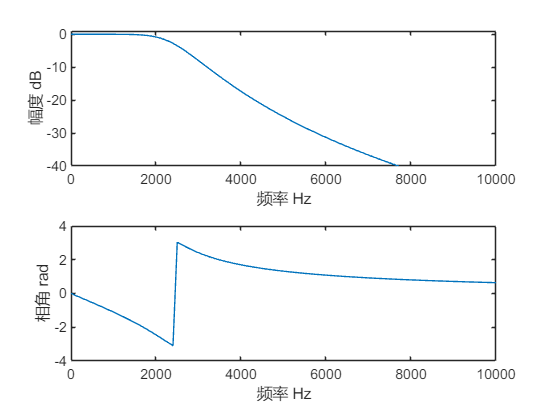

% 模拟低通滤波器
% 通带：0-fp，阻带：fs-inf
% fp = 2400
% fs = 5000
% Rp = 3dB  通带内最大衰减
% Rs = 25dB 阻带内最小衰减
clear;
fp = 2400;
fs = 5000;
Rp = 3;
Rs = 25;
% buttord用来根据指标计算阶数和截止频率
[n,fn] = buttord(fp,fs,Rp,Rs,'s');% n - 阶数    fn - 截止频率
Wn = 2 * pi * fn;
[b,a] = butter(n,Wn,'s');
f = 0:100:10000;        % 观察范围
s = 1i * 2 * pi * f;
H_s = polyval(b,s)./polyval(a,s);   % 滤波器的频率响应函数

figure(1);
subplot(2,1,1);plot(f,20 * log10(abs(H_s)));
axis([0 10000 -40 1]);
xlabel('频率 Hz');ylabel('幅度 dB');
subplot(2,1,2);plot(f,angle(H_s));
xlabel('频率 Hz');ylabel('相角 rad');

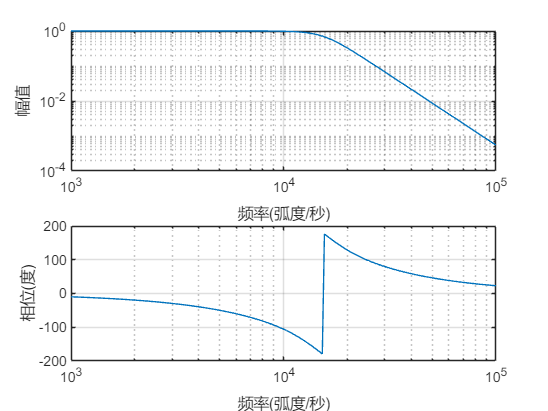


figure(2);
freqs(b,a);